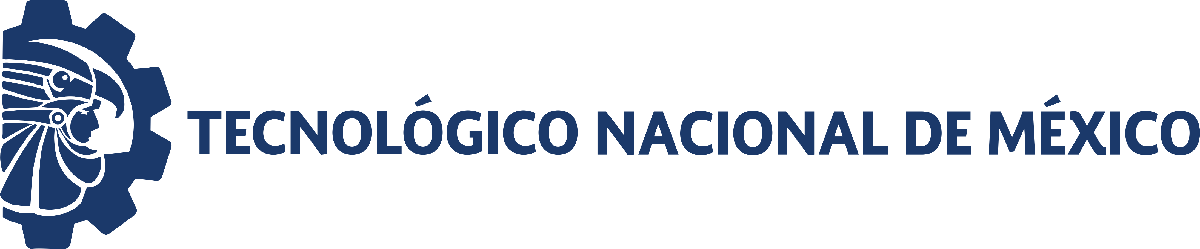                                 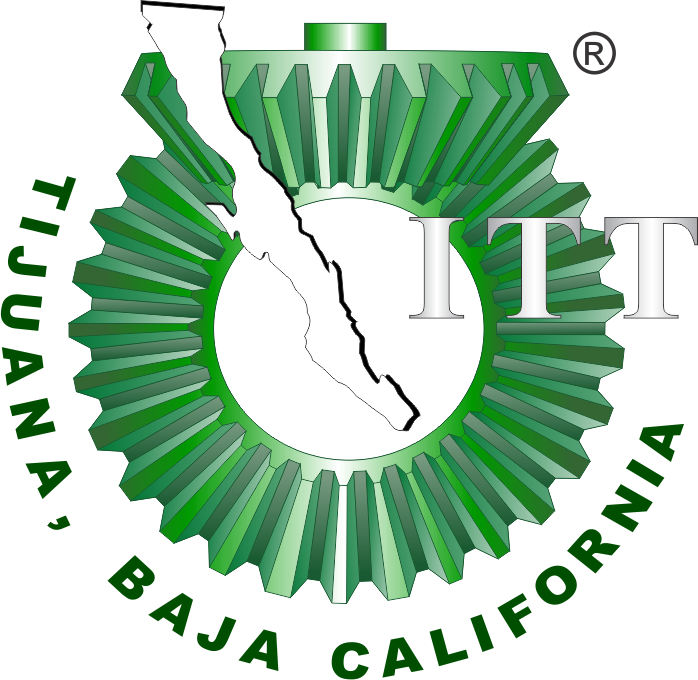

# Proyecto final: Fibrosis pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

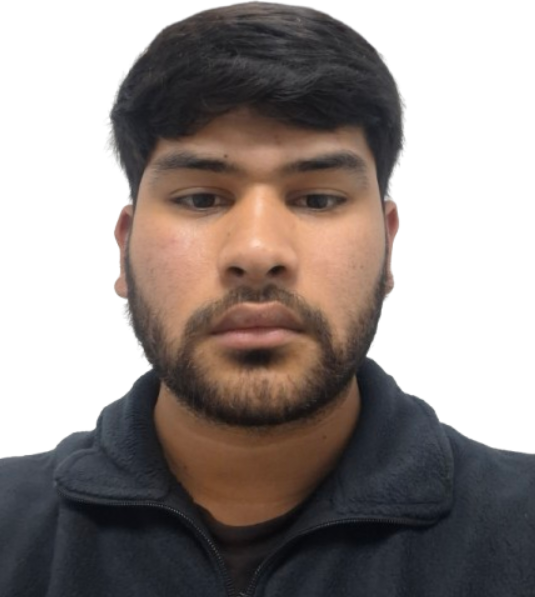

Nombre del alumno: Tapia Garcia Jahzeel Abisai

Número de control: 22210798

Correo institucional: l22210798**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx **

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '30';
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Rendimiento del controlador

kl= 1929.4827

Rise Time = 0.00142s

Setting Time = 0.00257 s

Overshoot = 0.0%

Peak = 1

## **Respuesta Lazo Abierto**

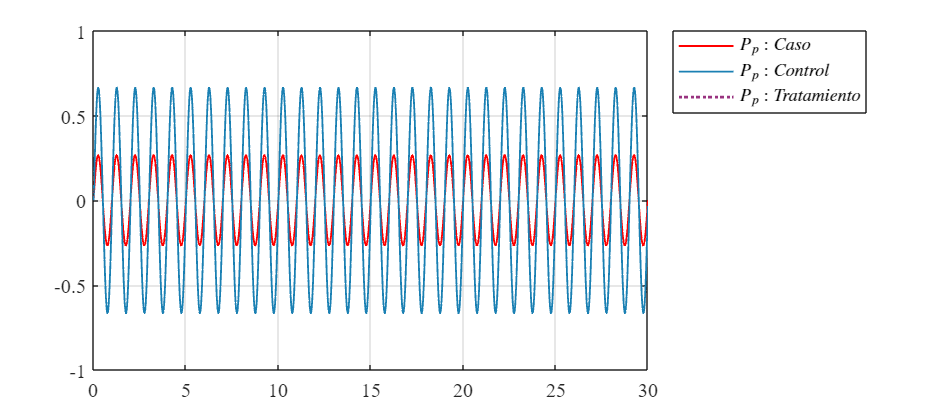

file = 'Lazoabierto';
open_system(file);
x = sim(file,parameters);
opt = 1;
plotsignals(x.t, x.Ppx,x.Ppy, opt);

## Respuesta Lazo Cerrado 

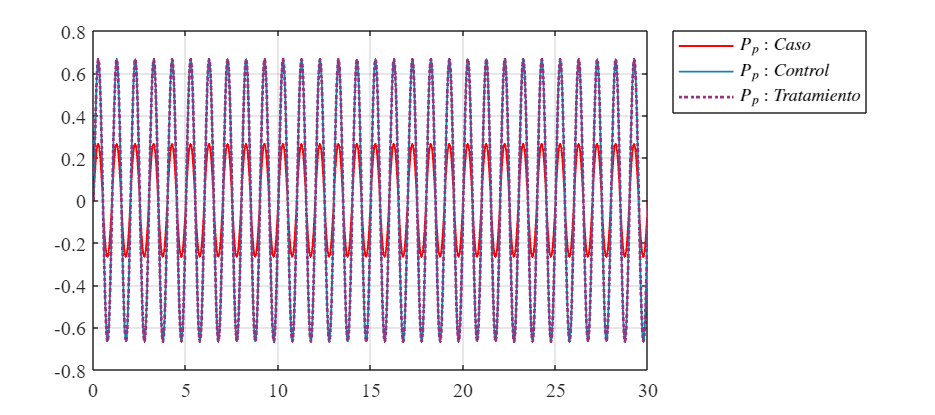

file = 'LazoCerrado';
open_system(file);
x = sim(file, parameters);
opt = 2;
plotsignals(x.t, x.Ppx, x.Ppy, x.Ppz, opt);

function plotsignals(t, Ppx, Ppy, Ppz,opt)
    set(figure(), 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 18, 8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    
    rojo=[1,0,0];
    morado=[.6,.2,.5];
    azul=[.1,.5,.7];
    
    hold on; grid on; box on;
    
    plot(t, Ppx, 'LineWidth', 1, 'Color', rojo);      % Caso: Paciente con fibrosis pulmonar
    plot(t, Ppy, 'LineWidth', 1, 'Color', azul);    % Control: Paciente sano
    plot(t, Ppz, ':', 'LineWidth', 1.5, 'Color', morado); % Tratamiento
    
    
    L = legend('$P_{p}:Caso$', ...
               '$P_{p}:Control$',...
               '$P_{p}:Tratamiento$');
    set(L, 'Interpreter','Latex','Location','northeastoutside','Box','on');
end
